# ECEN 100L Project 1

## By: Ayden Dauenhauer and John Hoang

## Part 1

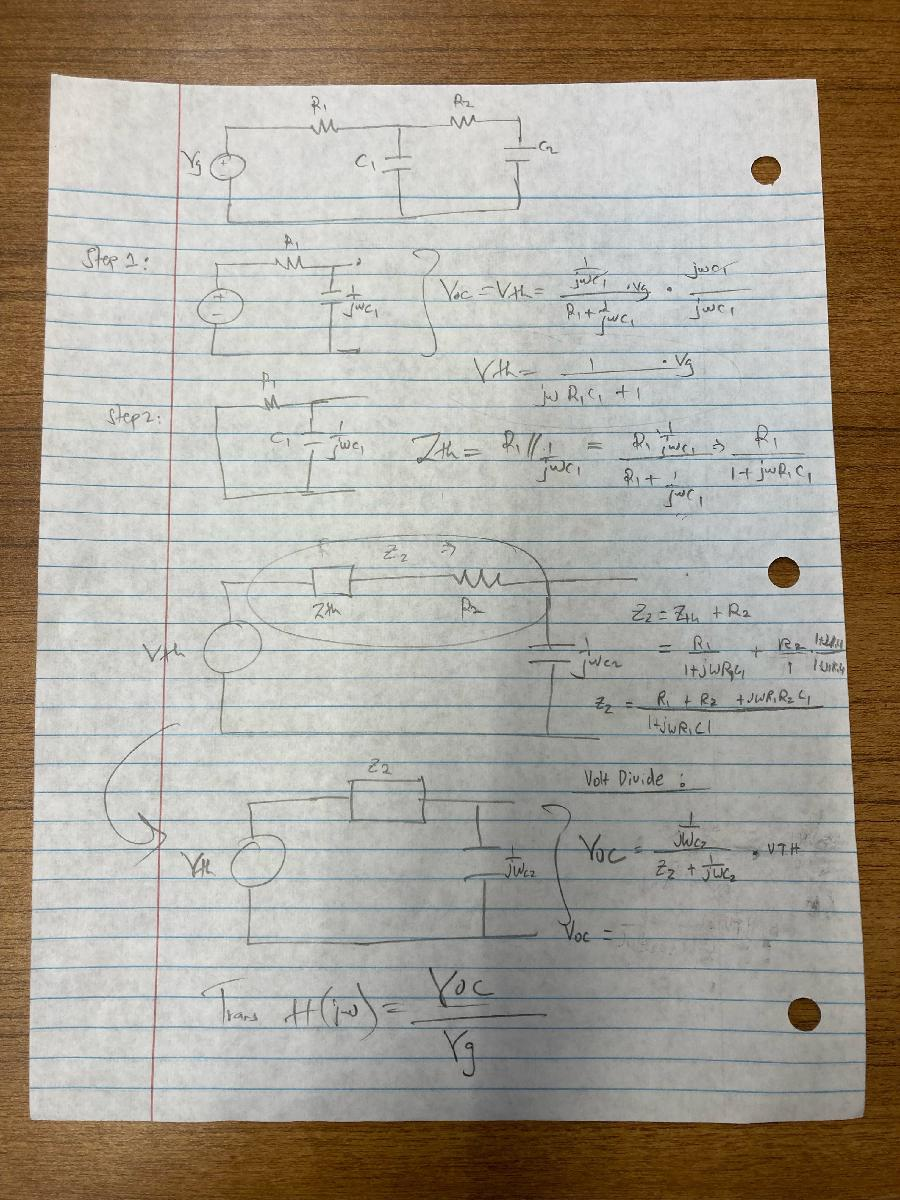

## Part 2

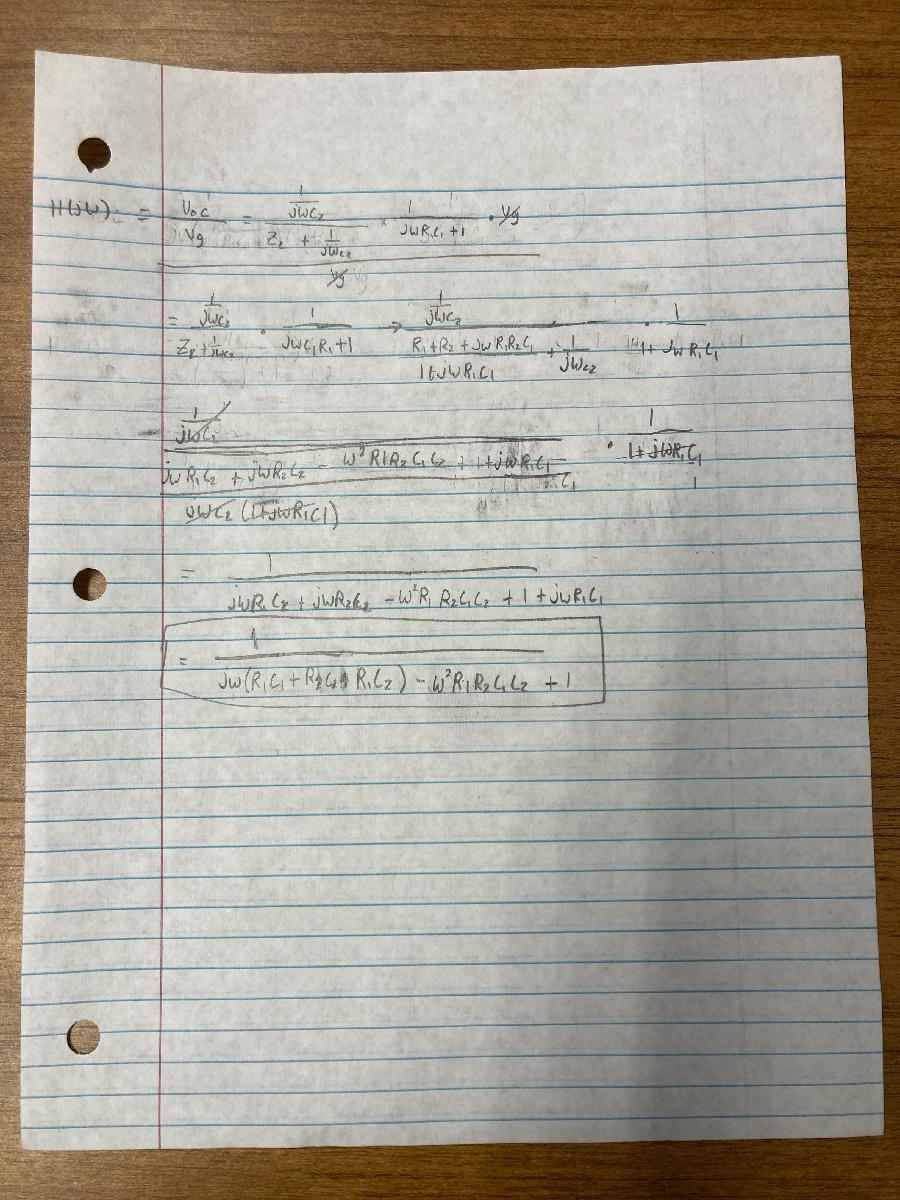

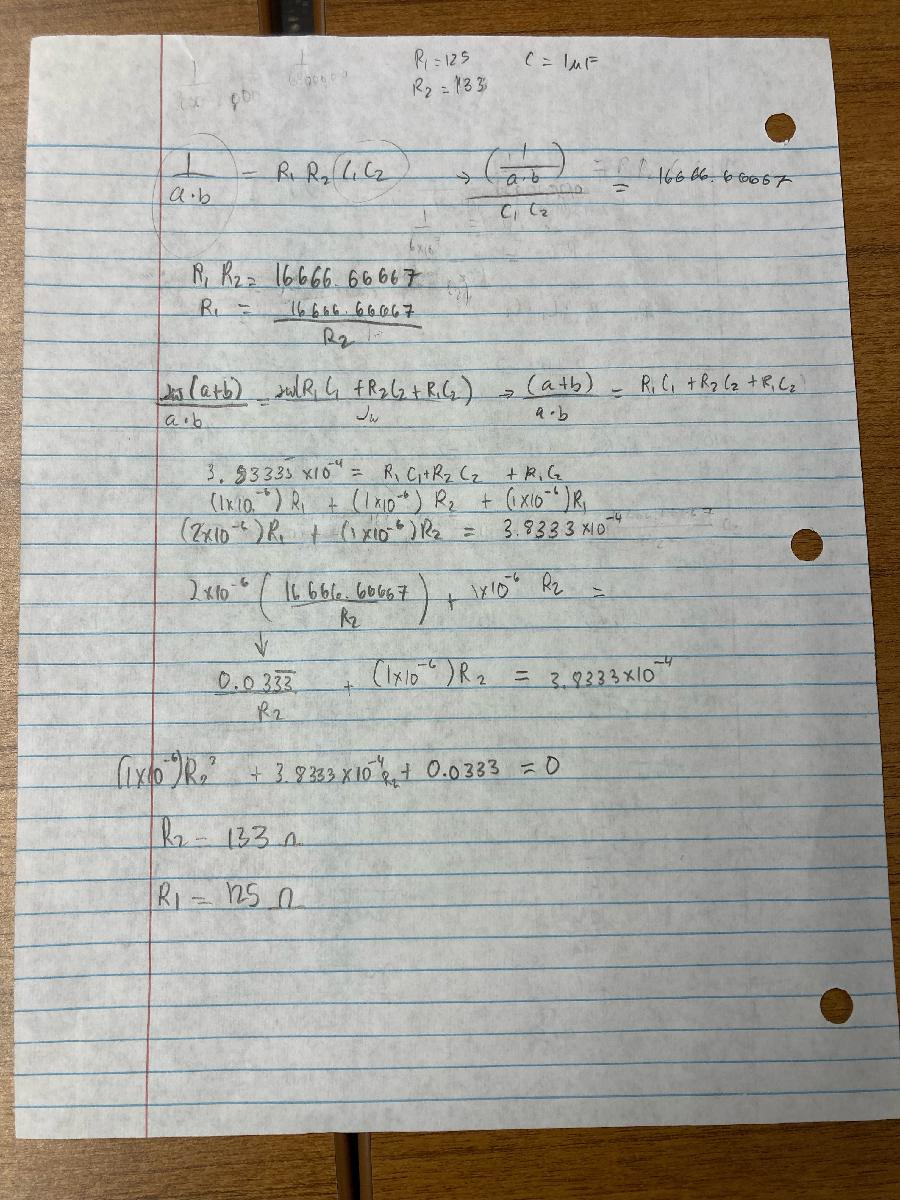

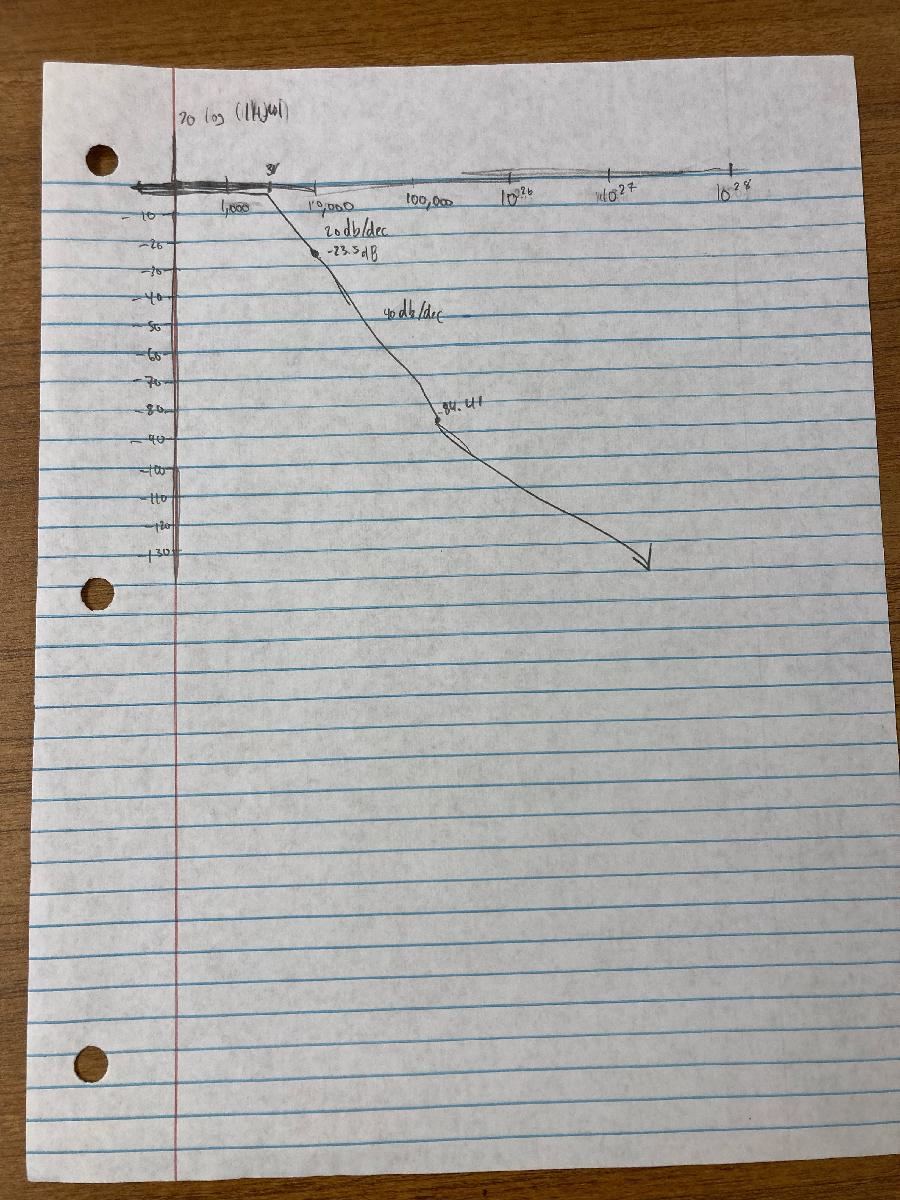

## Part 3

R1 = 125;
R2 = 133;
C1 = 1e-6;
C2 = 1e-6;
G = [1, 0, 0;
     -1/R1, 1/R1 + 1/R2, -1/R2;
     0, -1/R2, 1/R2];
C = [0, 0, 0;
     0, C1, 0;
     0, 0, C2];
b = [1; 0; 0];

w=1:100:10e6;

F = freqresp4(G,C,b,w);

semilogx(w,F)
grid on

## Part 4

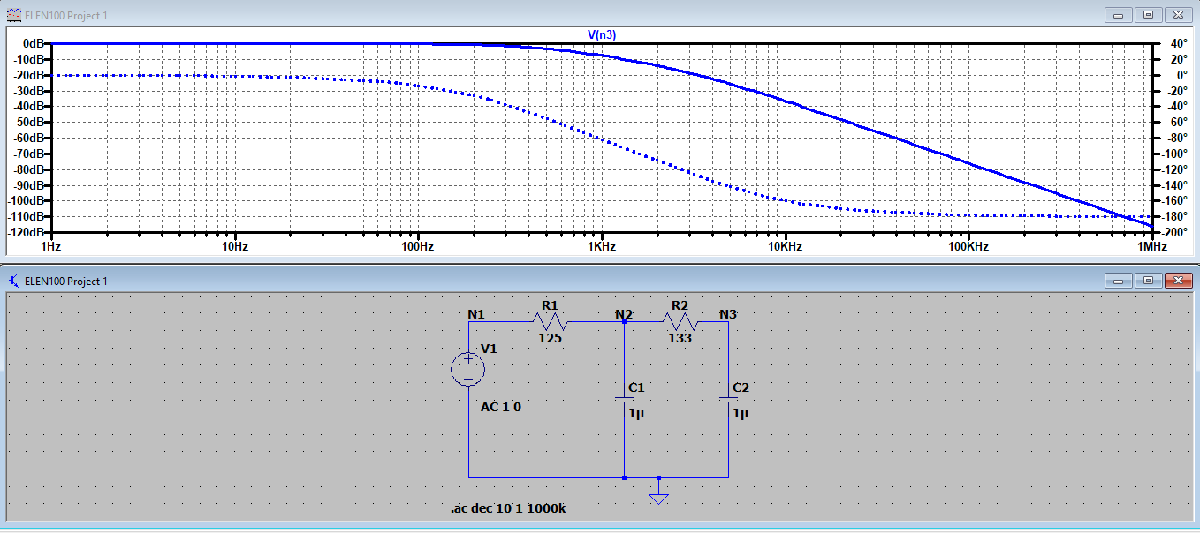

## Part 5

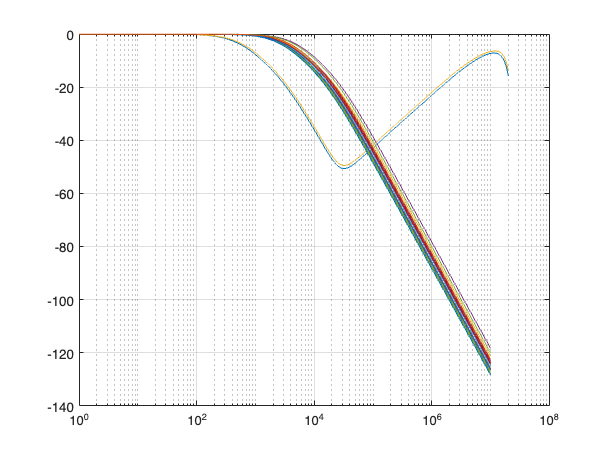

QX = [125, 133, 1e-6, 1e-6];
w = 1:100:10e6;
b = [1; 0; 0];
num = 20;

F = freqresp5(QX,b,w,num);
semilogx(w,F)
grid on

function F = freqresp4(G,C,b,w)

mag = zeros(3,1);
% We need to initialize vector mag, in order not to confuse Matlab.

for k = 1 : length(w)
    omega = w(k);
    % Omega is the next frequency in vector w.

    A = G + 1i*omega*C;
    x = A\b;
    % Vector x contains the solution of the node voltage equations in complex form.

    mag = [mag abs(x)];
    % The function abs(x) computes the magnitudes of all voltages.
    % These magnitudes are stored as a new column in matrix mag.
end

% Each column of matrix mag now contains voltage magnitudes computed at a particular frequency.
% Note, however, that the first column of this matrix is essentially redundant.
% It is a vector of zeros that % serves only as a place holder.

V3 = mag(3,2 : length(w) + 1);
% Since we are interested only in V3, we will extract row 3 of matrix mag (and ignore the first column).
F = 20*log10(V3);
end

function F = freqresp5(QX,b,w,num)
    % QX is a vector that contains all the nominal element values.
    % Resistors are listed first (as Q(1),Q(2) and Q(3)), the capacitors (Q(4)).
    % num is the number of different cases that we wish to simulate.
    F=[];
    for s = 1:num
        Q = variation(QX);
        % This function produces random variations of the element % values, which are within 20% of the nominal ones.
        G = zeros(3,3); C = zeros(3,3);
        
        % This line saves us some time, since we now need to enter only the nonzero elements in G and C.
        G(1,1) = 1; 
        G(2,1) = -1/Q(1); 
        G(2,2) = 1/Q(1) + 1/Q(2); 
        G(2,3) = -1/Q(2);
        G(3,2) = -1/Q(2); 
        G(3,3) = 1/Q(2);
        C(2,2) = Q(4);
        C(3,3) = Q(4);

        
        % For each new set of element values, matrices G, C and L must % be recomputed.
        mag = zeros(3,1);
        
        % Vector mag is initialized.
        for k = 1:length(w)
            omega = w(k);
            % Omega is the next frequency in w.
            A = G + 1i*omega*C;
            x=A\b;
            % Vector x contains the solution of the node voltage equations in complex form.
            mag = [mag abs(x)];
            % The magnitudes of all voltages as stored as a new column in matrix mag.
        end
    
        V3 = mag(3,2:length(w)+1);
        % Since we are interested only in V3, we will extract row 3 of matrix mag (and ignore the first column).
        FX = 20*log10(V3);
        F = [F;FX];
    % Each row of vector F corresponds to a different set of element values.
    % You can plot the all at once, using the command semilogx(w,F).
    end
end

function Q=variation(R)
% This function produces random variations of the elements of vector R.
% Which are within 20% of the nominal ones.
m = length(R);
g = ones(1,m) + 0.5*rand(1,m);
% Function rand(1,m) generates a random vector of size 1xm whose elements are between 0 and 1.
% The elements of vector % g are therefore random numbers with values between 1 and 1.5.
Q = 0.8*(R.*g);
% Each element of R is multiplied by a random number between 1 and 1.5.
% The additional multiplication by 0.8 secures that the elements of Q satisfy: 0.8*R(i)<Q(i)<1.2*R(i).
% In other words, the elements of Qare % within 20% of the values in R.
end

## Part 6